产生瑞利衰落和莱斯衰落信道

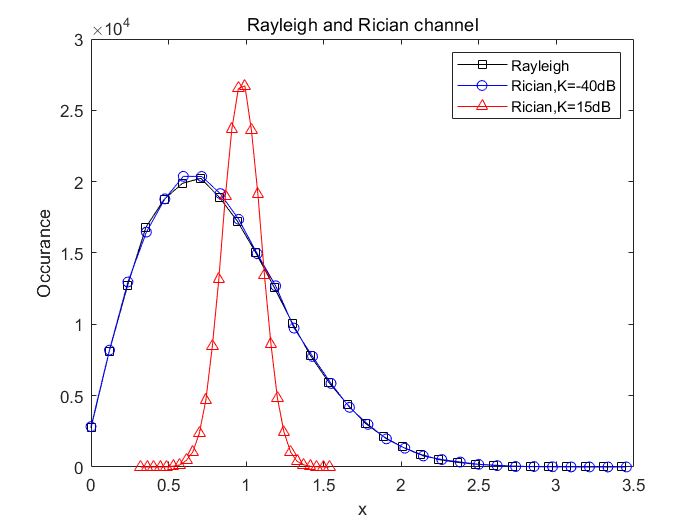

clear,clf,clc,close
N = 200000;
level = 30;
K_dB = [-40 15];
gss = ['k-s';'b-o';'r-^'];
Rayleigh_ch = Ray_model(N);
x=histogram(abs(Rayleigh_ch(1,:)),level);
temp = zeros(2,level,3);
temp(:,:,1) = [x.BinEdges(1,1:length(x.BinEdges)-1);x.Values];
close
Rician_ch = zeros(length(K_dB),N);
for ni = 1:length(K_dB)
    Rician_ch(ni,:)=Ric_model(K_dB(ni),N);
    x=histogram(abs(Rician_ch(ni,:)),level);
    temp(:,:,ni+1) = [x.BinEdges(1,1:length(x.BinEdges)-1);x.Values];
    close
end
for ni = 1:length(K_dB)+1
    plot(temp(1,:,ni),temp(2,:,ni),gss(ni,:)); hold on
end
xlabel('x'),ylabel('Occurance')
legend('Rayleigh','Rician,K=-40dB','Rician,K=15dB')
title(['Rayleigh and Rician channel'])